% Dane dla OZ

data = load("Pomiary\dane_platorma_bez_obciazenia\Nowe\Obrot_z.mat");

ax = data.out.acc(:, 1);
ay = data.out.acc(:, 2);
az = data.out.acc(:, 3);

gx = data.out.gyro(:, 3);
gy = data.out.gyro(:, 2);
gz = data.out.gyro(:, 1);

t = 0:0.01:27.99;

fs = 85;        % częstotliwość próbkowania [Hz]
fc = 3;         % częstotliwość odcięcia filtru [Hz]

[b, a] = butter(2, fc/(fs/2), 'low');

ax_f_4 = filter(b, a, ax);
ay_f_4 = filter(b, a, ay);
az_f_4 = filter(b, a, az);

gx_f_4 = filter(b, a, gx);
gy_f_4 = filter(b, a, gy);
gz_f_4 = filter(b, a, gz);

avg_x = mean(gx_f_4(1:1000))

avg_x = single
0.0370

avg_y = mean(gy_f_4(1:1000))

avg_y = single
0.0901

avg_z = mean(gz_f_4(1:1000))

avg_z = single
0.1418


% Plot acc
plt = plot(t, [ax_f_4, ay_f_4, az_f_4], LineWidth=1.5)

plt =   3×1 Line array:

  Line
  Line
  Line


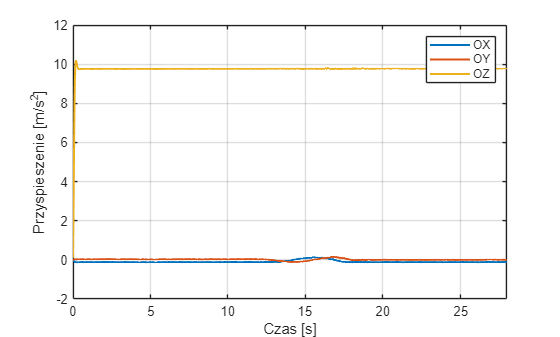

plt(1).Color = [0.0000 0.4470 0.7410];
plt(2).Color = [0.8500 0.3250 0.0980];
plt(3).Color = [0.9290 0.6940 0.1250];

grid on
legend('OX', 'OY', 'OZ')
ylabel("Przyspieszenie [m/s^2]")
xlabel("Czas [s]")
xlim([0, 28])


%plot gyro
plt = plot(t, [gx_f_4, gy_f_4, gz_f_4], LineWidth=1.5)

plt =   3×1 Line array:

  Line
  Line
  Line


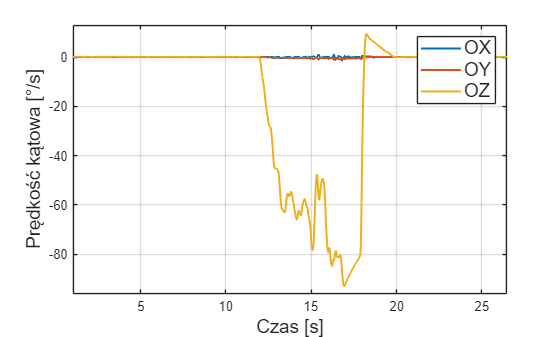

plt(1).Color = [0.0000 0.4470 0.7410];
plt(2).Color = [0.8500 0.3250 0.0980];
plt(3).Color = [0.9290 0.6940 0.1250];

grid on
legend('OX', 'OY', 'OZ', 'FontSize', 14)
ylabel("Prędkość kątowa [°/s]", 'FontSize', 14)
xlabel("Czas [s]", 'FontSize', 14)
xlim([0, 28])


%plot gyro X Y
plt = plot(t, [gx_f_4, gy_f_4], LineWidth=1.5)

plt =   2×1 Line array:

  Line
  Line


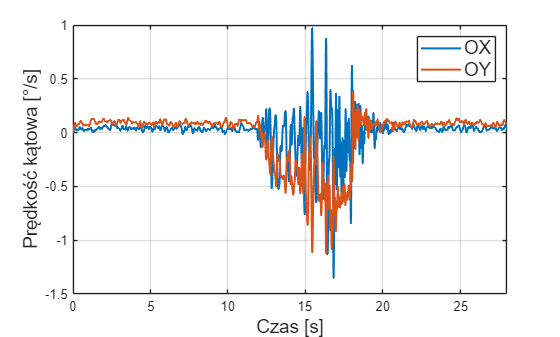

plt(1).Color = [0.0000 0.4470 0.7410];
plt(2).Color = [0.8500 0.3250 0.0980];

grid on
legend('OX', 'OY', 'FontSize', 14)
ylabel("Prędkość kątowa [°/s]", 'FontSize', 14)
xlabel("Czas [s]", 'FontSize', 14)
xlim([0, 28])

% Dane dla OX

data = load("Pomiary\dane_platorma_bez_obciazenia\Nowe\Obrot_wew_pier.mat");

ax = data.out.acc(2500:4700, 1);
ay = data.out.acc(2500:4700, 2);
az = data.out.acc(2500:4700, 3);

gx = data.out.gyro(2500:4700, 3);
gy = data.out.gyro(2500:4700, 2);
gz = data.out.gyro(2500:4700, 1);

t = 0:0.01:22;

fs = 85;        % częstotliwość próbkowania [Hz]
fc = 3;         % częstotliwość odcięcia filtru [Hz]

[b, a] = butter(2, fc/(fs/2), 'low');

ax_f_4 = filter(b, a, ax);
ay_f_4 = filter(b, a, ay);
az_f_4 = filter(b, a, az);

gx_f_4 = filter(b, a, gx);
gy_f_4 = filter(b, a, gy);
gz_f_4 = filter(b, a, gz);


avg_x = mean(ax_f_4(1:400))

avg_x = single
9.6435

avg_y = mean(ay_f_4(1:400))

avg_y = single
-0.6022

avg_z = mean(az_f_4(1:400))

avg_z = single
-0.3094

minimum = min(az_f_4)

minimum = single
-0.3706

maximum = max(az_f_4)

maximum = single
-0.0034


% Plot acc
plt = plot(t, [ax_f_4, ay_f_4, az_f_4], LineWidth=1.5)

plt =   3×1 Line array:

  Line
  Line
  Line


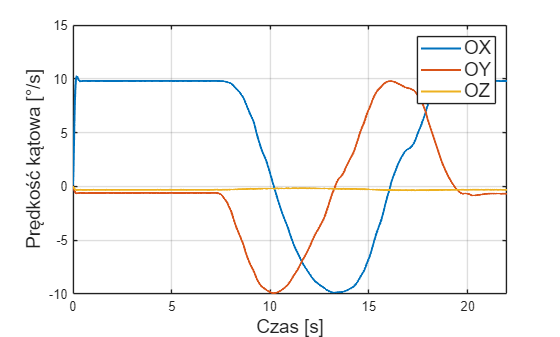

plt(1).Color = [0.0000 0.4470 0.7410];
plt(2).Color = [0.8500 0.3250 0.0980];
plt(3).Color = [0.9290 0.6940 0.1250];

grid on
legend('OX', 'OY', 'OZ', 'FontSize', 14)
ylabel("Prędkość kątowa [°/s]", 'FontSize', 14)
xlabel("Czas [s]", 'FontSize', 14)
xlim([0, 22])


% Plot gyro
plt = plot(t, [gx_f_4, gy_f_4, gz_f_4], LineWidth=1.5)

plt =   3×1 Line array:

  Line
  Line
  Line


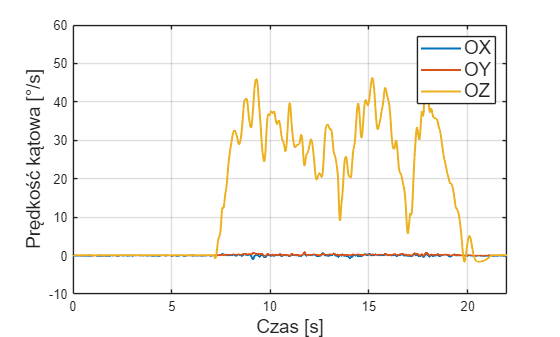

plt(1).Color = [0.0000 0.4470 0.7410];
plt(2).Color = [0.8500 0.3250 0.0980];
plt(3).Color = [0.9290 0.6940 0.1250];

grid on
legend('OX', 'OY', 'OZ', 'FontSize', 14)
ylabel("Prędkość kątowa [°/s]", 'FontSize', 14)
xlabel("Czas [s]", 'FontSize', 14)
xlim([0, 22])


% Plot gyro X Y
plt = plot(t, [gx_f_4, gy_f_4], LineWidth=1.5)

plt =   2×1 Line array:

  Line
  Line


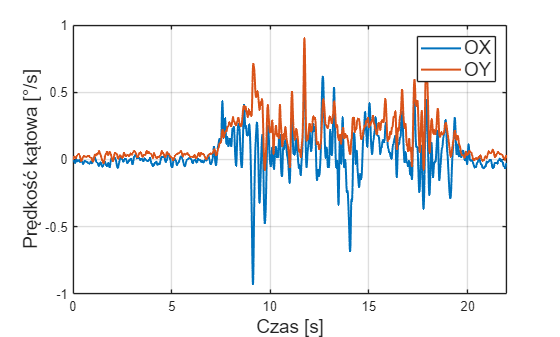

plt(1).Color = [0.0000 0.4470 0.7410];
plt(2).Color = [0.8500 0.3250 0.0980];

grid on
legend('OX', 'OY', 'FontSize', 14)
ylabel("Prędkość kątowa [°/s]", 'FontSize', 14)
xlabel("Czas [s]", 'FontSize', 14)
xlim([0, 22])

% Dane dla OY

data = load("Pomiary\dane_platorma_bez_obciazenia\Nowe\Obrot_zew_pier.mat");

ax = data.out.acc(600:1800, 1);
ay = data.out.acc(600:1800, 2);
az = data.out.acc(600:1800, 3);

gx = data.out.gyro(600:1800, 3);
gy = data.out.gyro(600:1800, 2);
gz = data.out.gyro(600:1800, 1);

t = 0:0.01:12;

fs = 85;        % częstotliwość próbkowania [Hz]
fc = 3;         % częstotliwość odcięcia filtru [Hz]

[b, a] = butter(2, fc/(fs/2), 'low');

ax_f_4 = filter(b, a, ax);
ay_f_4 = filter(b, a, ay);
az_f_4 = filter(b, a, az);

gx_f_4 = filter(b, a, gx);
gy_f_4 = filter(b, a, gy);
gz_f_4 = filter(b, a, gz);

minimum_x = min(ax_f_4)

minimum_x = single
-9.8656

maximum_x = max(ax_f_4)

maximum_x = single
10.1975

minimum_y = min(ay_f_4)

minimum_y = single
-9.9347

maximum_y = max(ay_f_4)

maximum_y = single
9.7399

minimum_z = min(az_f_4)

minimum_z = single
-0.3399

maximum_z = max(az_f_4)

maximum_z = single
-0.0028


% Plot acc
plt = plot(t, [ax_f_4, ay_f_4, az_f_4], LineWidth=1.5)

plt =   3×1 Line array:

  Line
  Line
  Line


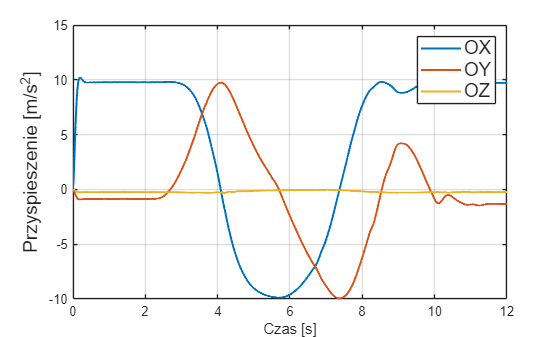

plt(1).Color = [0.0000 0.4470 0.7410];
plt(2).Color = [0.8500 0.3250 0.0980];
plt(3).Color = [0.9290 0.6940 0.1250];

grid on
legend('OX', 'OY', 'OZ', 'FontSize', 14)
ylabel("Przyspieszenie [m/s^2]", 'FontSize', 14)
xlabel("Czas [s]")
xlim([0, 12])


% Plot gyro
plt = plot(t, [gx_f_4, gy_f_4, gz_f_4], LineWidth=1.5)

plt =   3×1 Line array:

  Line
  Line
  Line


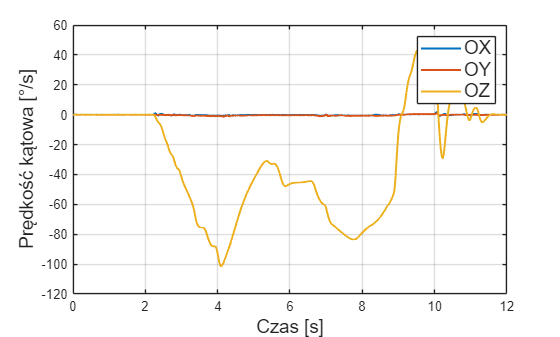

plt(1).Color = [0.0000 0.4470 0.7410];
plt(2).Color = [0.8500 0.3250 0.0980];
plt(3).Color = [0.9290 0.6940 0.1250];

grid on
legend('OX', 'OY', 'OZ', 'FontSize', 14)
ylabel("Prędkość kątowa [°/s]", 'FontSize', 14)
xlabel("Czas [s]", 'FontSize', 14)
xlim([0, 12])

% xline(9.5, 'r--', 'LineWidth', 1.5, 'HandleVisibility', 'off');

% Plot gyro X Y
plt = plot(t, [gx_f_4, gy_f_4], LineWidth=1.5)

plt =   2×1 Line array:

  Line
  Line


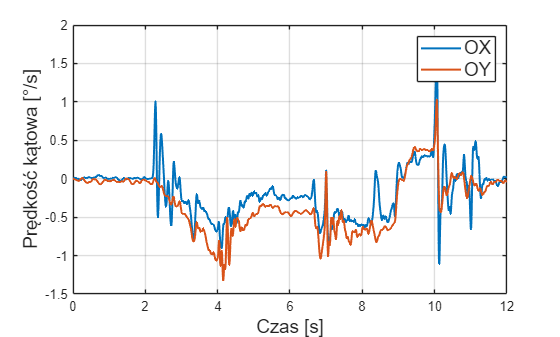

plt(1).Color = [0.0000 0.4470 0.7410];
plt(2).Color = [0.8500 0.3250 0.0980];

grid on
legend('OX', 'OY', 'FontSize', 14)
ylabel("Prędkość kątowa [°/s]", 'FontSize', 14)
xlabel("Czas [s]", 'FontSize', 14)
xlim([0, 12])

% xline(9.5, 'r--', 'LineWidth', 1.5, 'HandleVisibility', 'off');